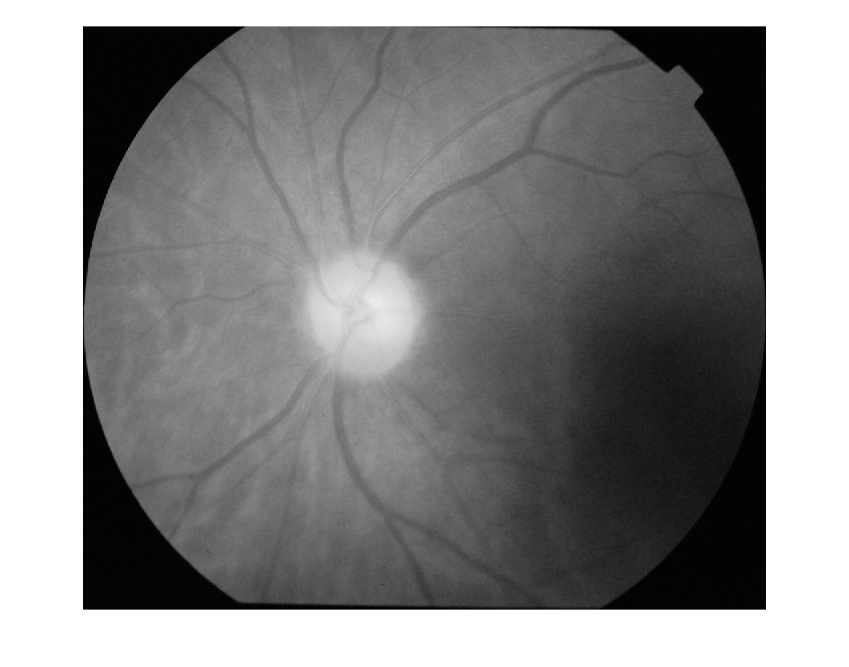

[image, pathname] = uigetfile('*.png');
I = imread(image);
HSV = rgb2hsv(I);

%Ambil value citra
V = HSV(:,:,3);
figure, imshow(V)

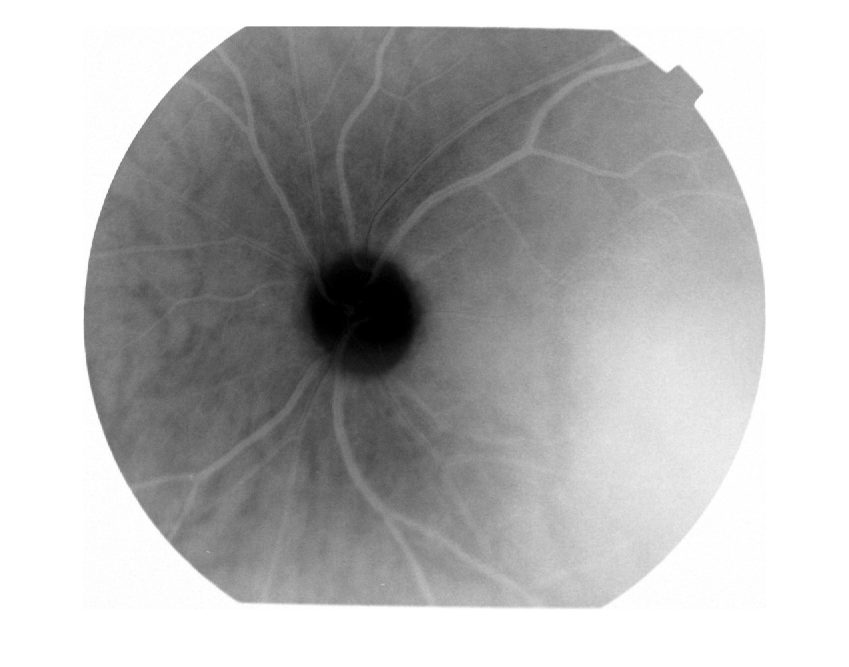

%Invert warna
figure, imshow(imcomplement(imadjust(V)))

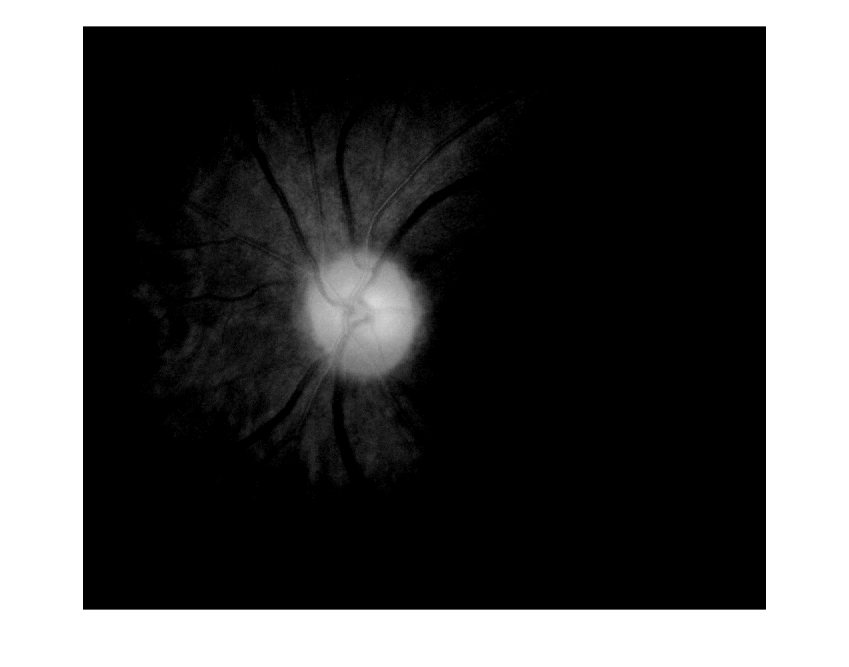

%Mengubah kontras citra gray
Vnew = V - imcomplement(V);
figure, imshow(Vnew)

level = graythresh(V);
ne = Vnew > level;
binaryImage = ne;
% Get rid of stuff touching the border
binaryImage = imclearborder(binaryImage);
fill = imfill(binaryImage,'holes');

se = strel('disk', 6)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


dil = imdilate(fill,se)

dil = 1750×2049 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

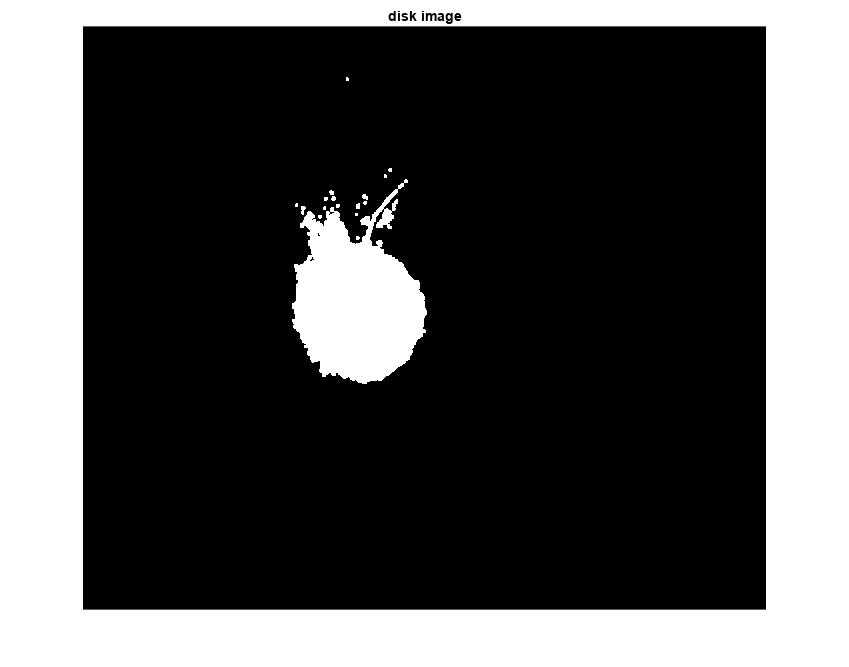

figure,imshow(dil)
title('disk image')

openim = imclose((imopen(dil, strel('diamond',25))), strel('arbitrary',40))

openim = 1750×2049 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

figure, imshow(openim)
N = nnz(openim);
disp(N)

      136524



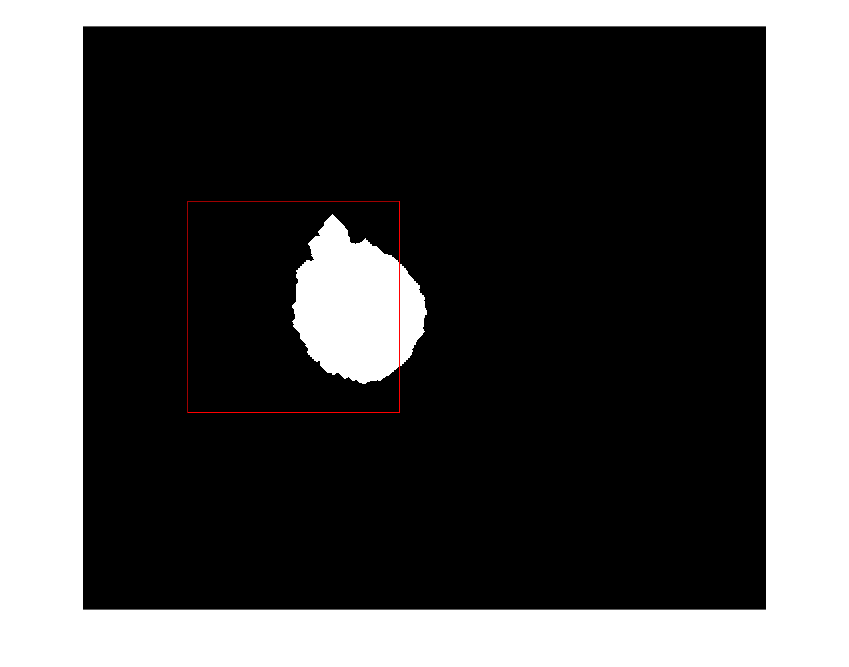

% Extract only the two largest blobs.
BW = binaryImage;
CC = bwconncomp(BW);
numPixels = cellfun(@numel,CC.PixelIdxList);
[biggest,idx] = max(numPixels);
BW(CC.PixelIdxList{idx}) = 0;
filteredForeground = BW;

% regionprops untuk mendapatkan informasi Area, Centroid, Bbox
s = regionprops(BW,'basic');
centroids = cat(1,s.Centroid);
bbox = cat(1,s.BoundingBox);
x = s(1).Centroid(1,1) - 1/2*(bbox(3));
y = s(1).Centroid(1,2) - 1/2*(bbox(4));
rectangle('Position',[x y bbox(3) bbox(4)],'EdgeColor','r')

%hold off
% Hitung Area, Luas BoundingBox, Titik tengah
display(s(1).Area);

     2



display(bbox(3)*bbox(4));

   4.0259e+05



display(s(1).Centroid);

  632.5000  842.0000

